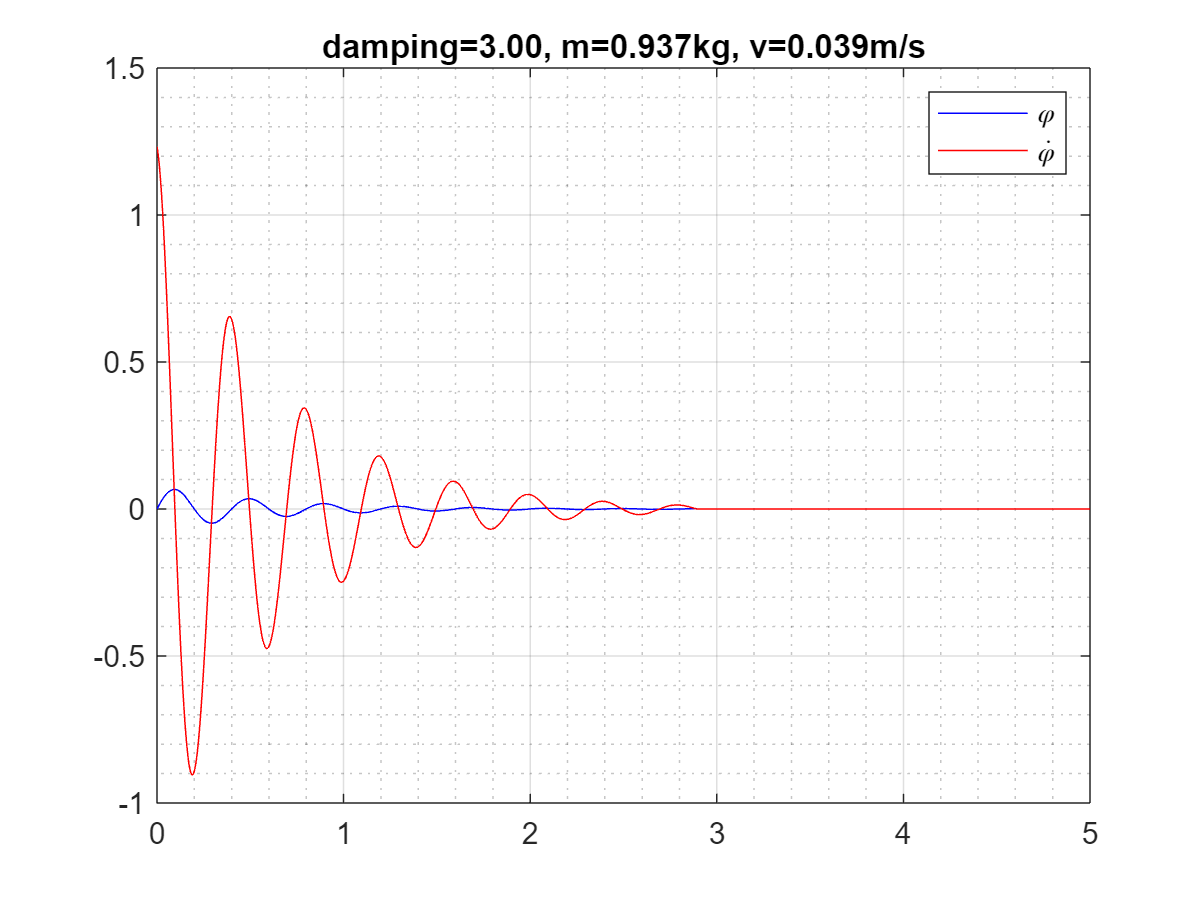

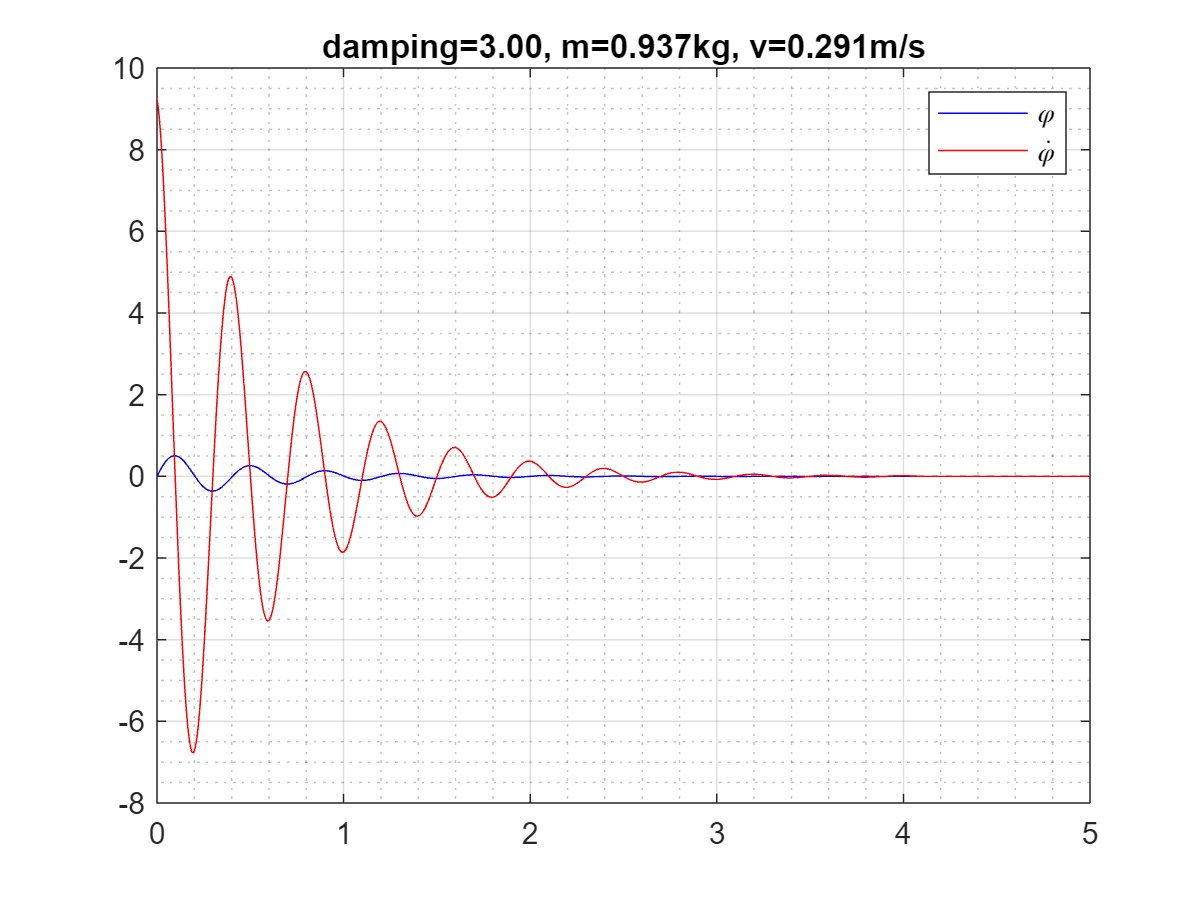

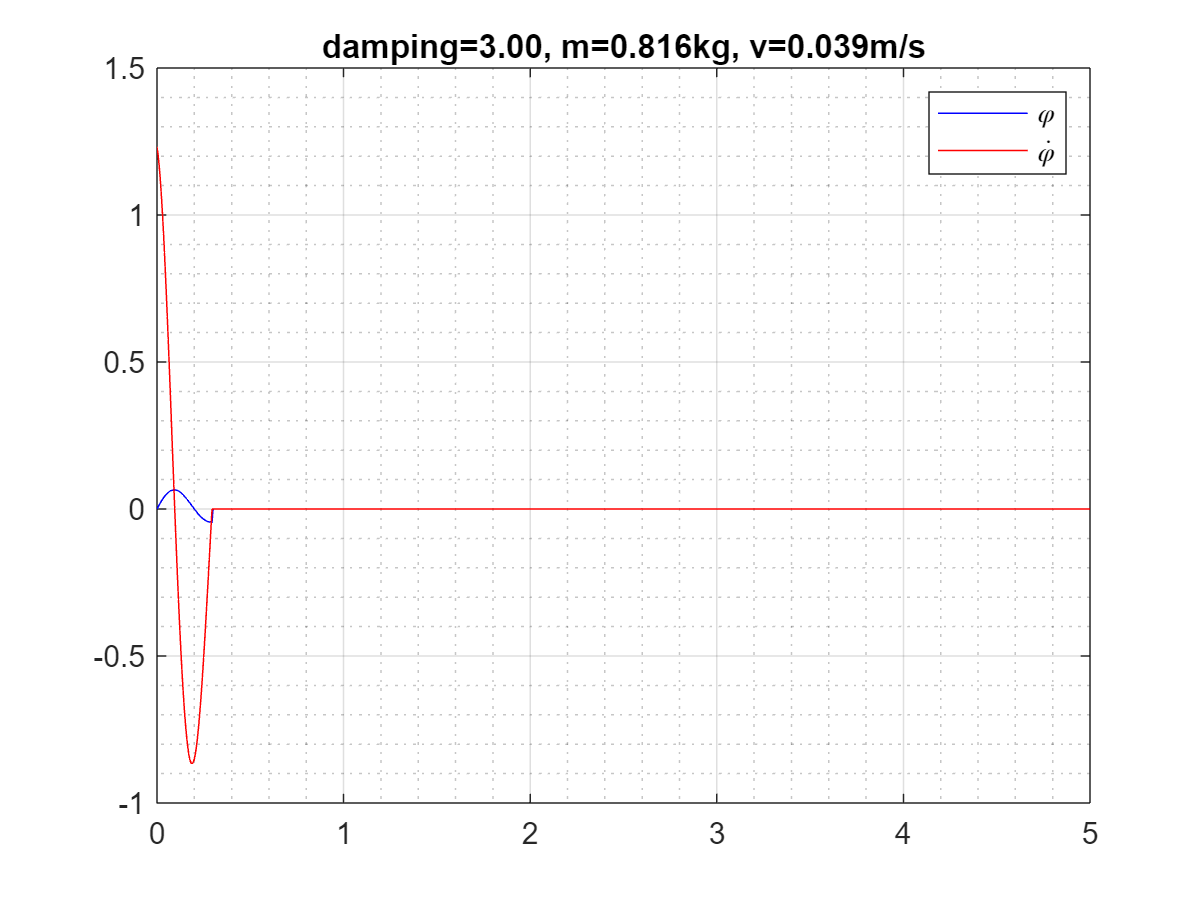

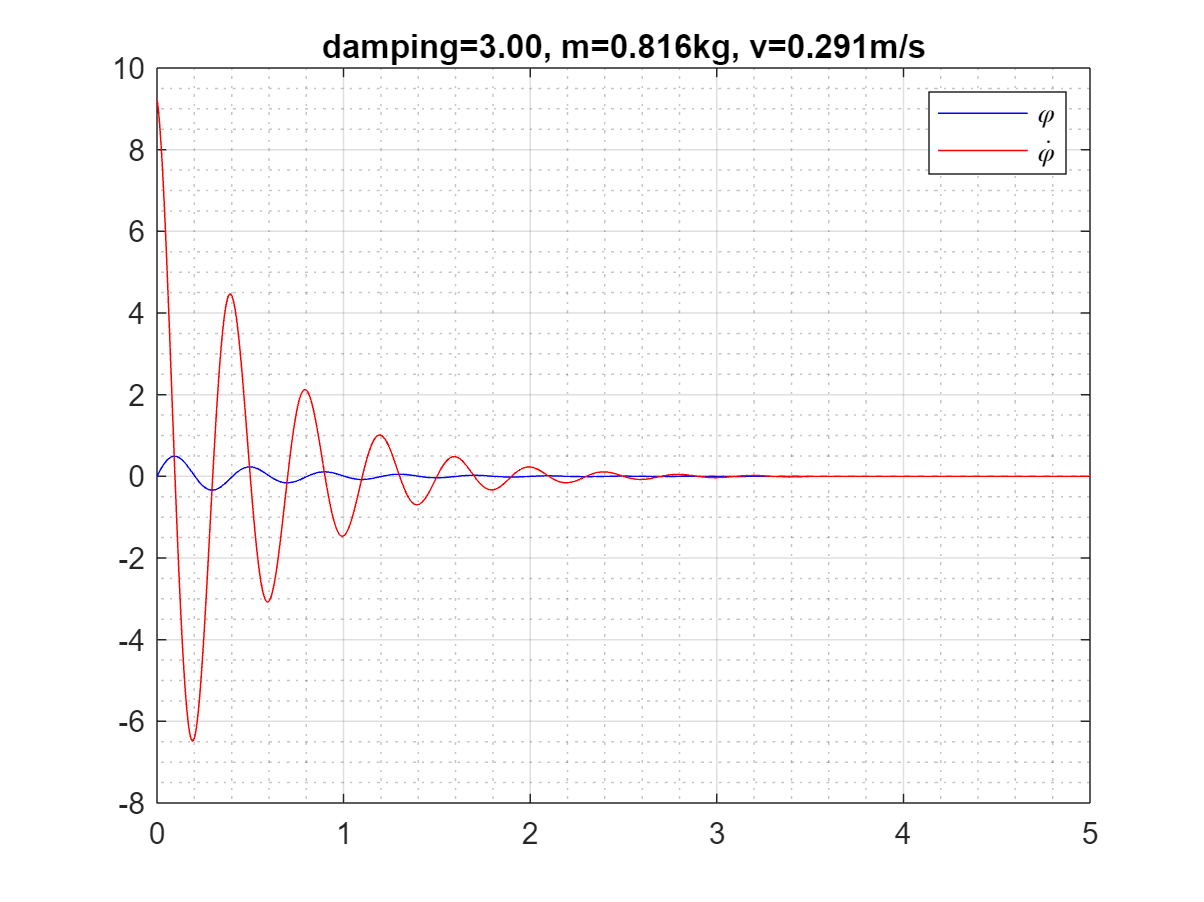

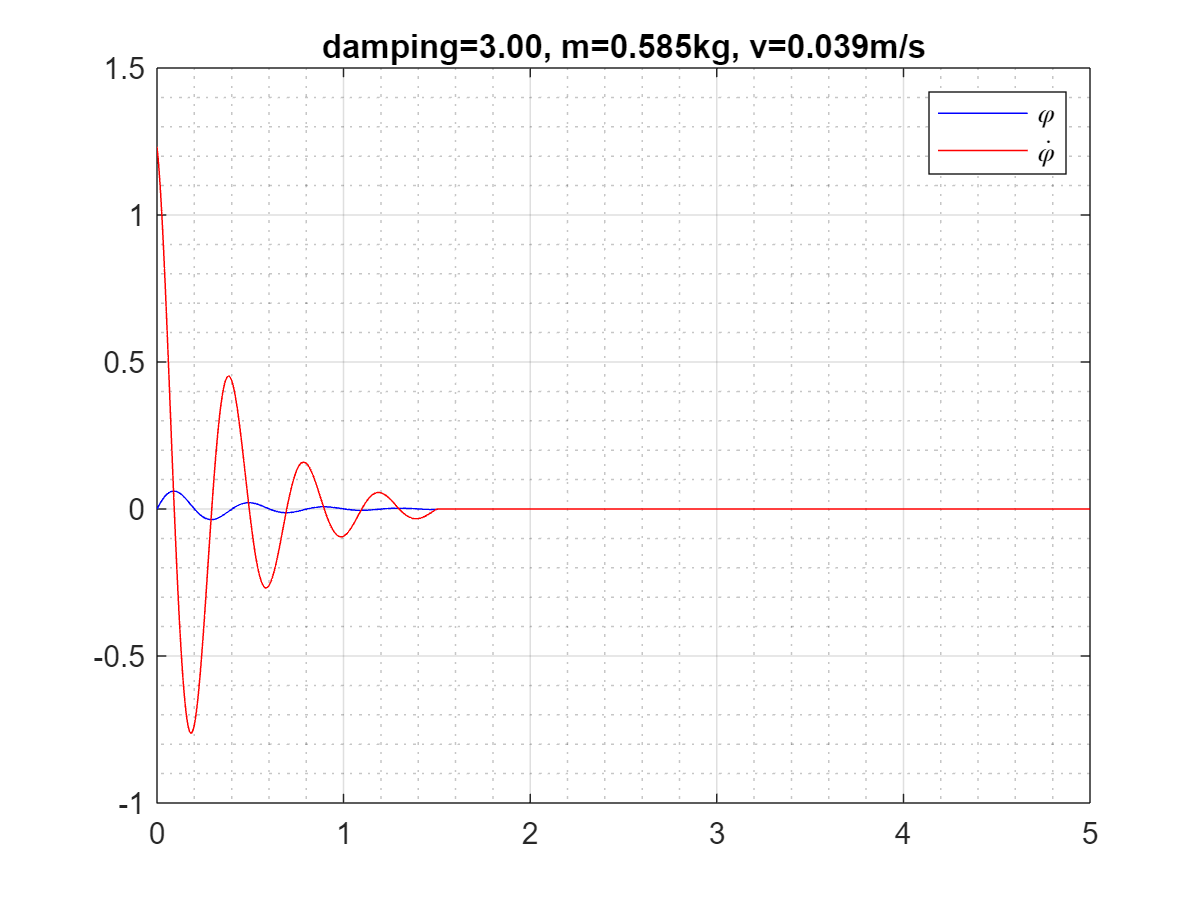

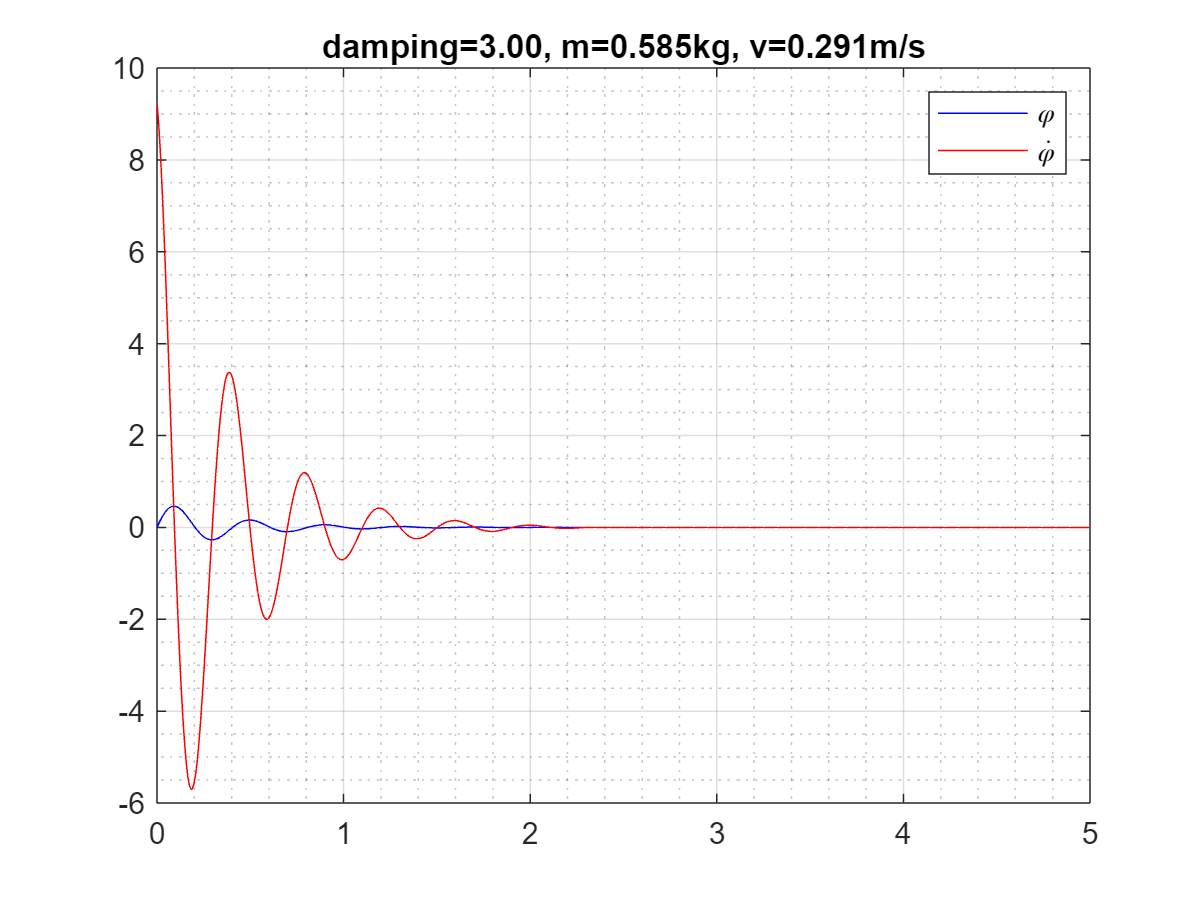

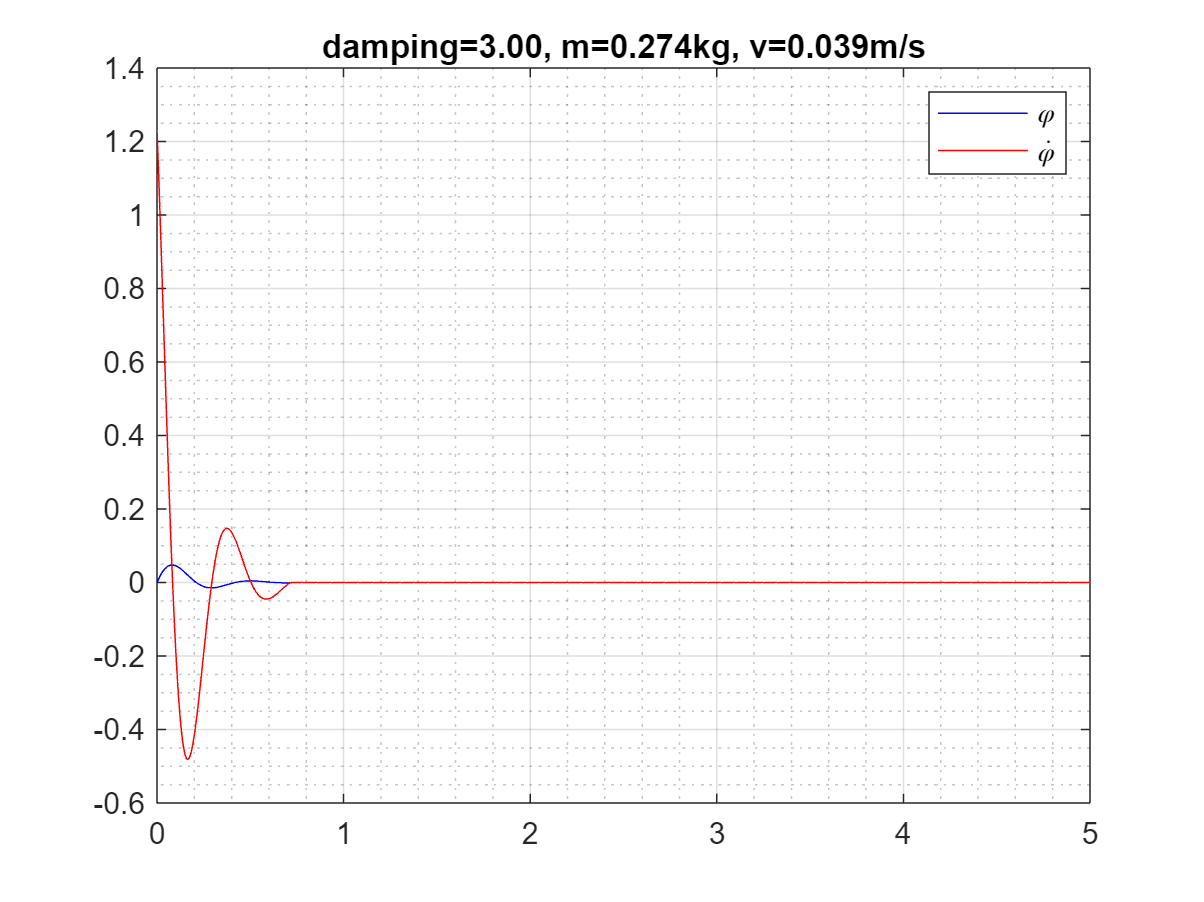

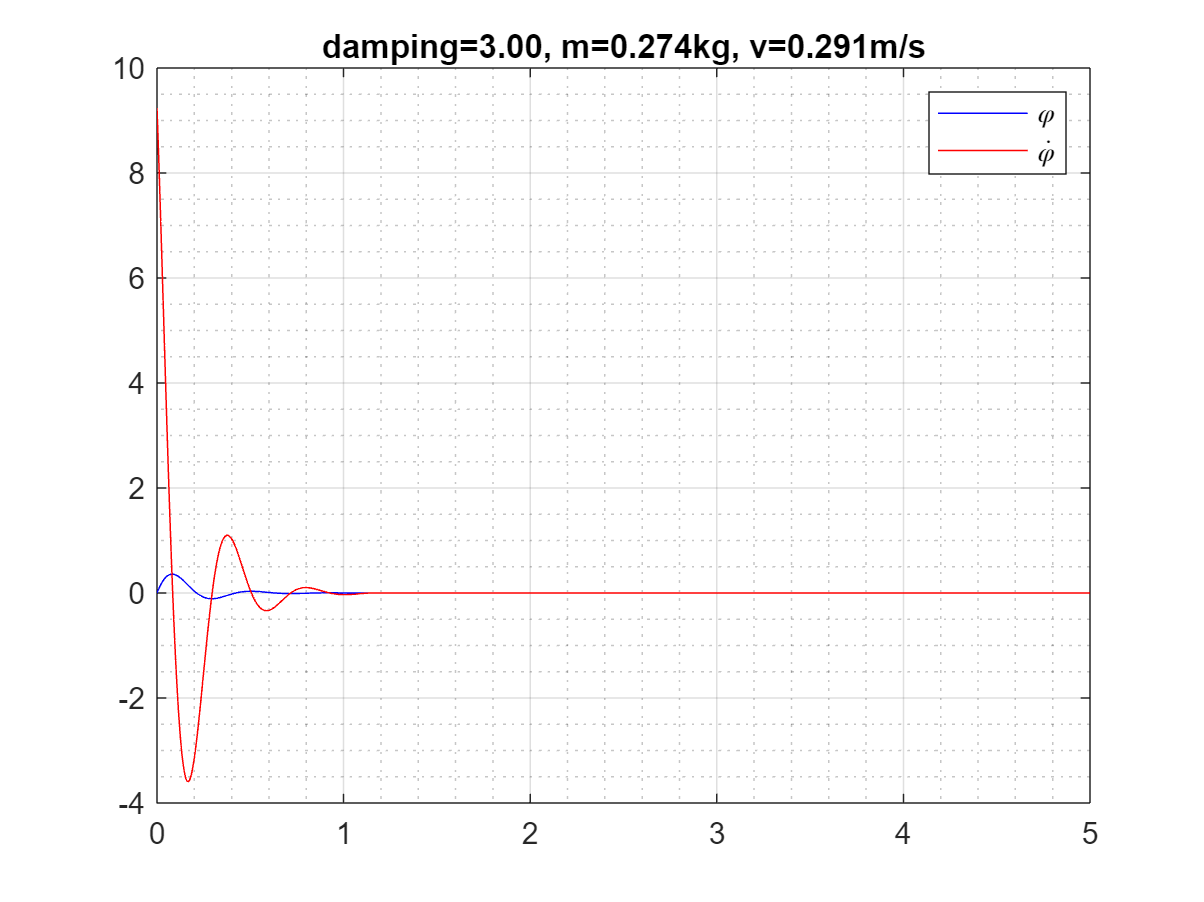

% based on: https://www.physicsandstuffiguess.com/pendulums/pendulumFriction.html
clear
do_plots = true;

% product measurements
l = 0.05;
d = 0.05;
masses = [0.937, 0.816, 0.585, 0.274, 0.138]; % 5 weight classes

% crane measurements
r = 0.185;
omega_K_deg = 12:90;
omega_K = omega_K_deg/360*2*pi; % LUT for crane speeds
start_velocities = omega_K * r;

% dynamics
damping = 3; % TODO - experiments
g = 9.81;
dt = 0.005;
t_end = 5;
time = 0:dt:t_end;

oscillation_times = zeros(length(masses), length(start_velocities));

for i = 1:length(masses)
    m = masses(i);
    I = (m/16) * d^2 + (m/3) * l^2;
    omega_0 = sqrt(m * g * l / (2*I));
    beta = damping/(2*m);
    % beta = omega_0; -> critically damped case

    % solve using Euler-Cromer -> gamma = phi_dot (cf. link above)
    phi = zeros(1,length(time));
    gamma = zeros(1,length(time));

    v_min_plotted = false;

    for j = 1:length(start_velocities)
        v = start_velocities(j);
        gamma(1) = sqrt(v^2*m/I);   % initial angular velocity

        for k = 1:length(time)-1
            % angular velocity at next step
            gamma(k+1) = gamma(k) + dt*(-2*beta*gamma(k) - omega_0^2 * sin(phi(k)));
            % use that angular velocity to fing the next angle
            phi(k+1) = phi(k) + dt*gamma(k+1);

            % break if phi_dot = gamma = 0 and phi <= 1° = 0.0175rad
            if abs(gamma(k+1)) <= 0.0005 && phi(k+1) <= 0.0175
                oscillation_times(i, j) = time(k+1);
                break
            end
        end

        if oscillation_times(i, j) == 0
            oscillation_times(i, j) = t_end;
        end

        % plot for min and max velocity of each mass
        if do_plots && (v_min_plotted == false || j == length(start_velocities))
            figure
            plot(time, phi, 'b')
            grid on
            grid minor
            hold on
            plot(time, gamma, 'r')

            legend('$\varphi$', '$\dot{\varphi}$', 'Interpreter', 'latex')
            title(sprintf('damping=%.2f, m=%.3fkg, v=%.3fm/s', damping, m, v))

            v_min_plotted = true;
            hold off
        end
    end
end


% print oscillation times LUT
file = fopen('oscillation_times_lut.st', 'w');
fprintf(file, '\tm_oscillationTimes: ARRAY [1..%.0f, %.0f..%.0f] OF REAL := [\n', [length(masses), min(omega_K_deg(:)), max(omega_K_deg(:))]);

% LUT usage in ST: t := m_oscillationTimes[<weight-class>, <omega-K-deg>];
format_spec = '\t\t%.5f, %.5f, %.5f, %.5f, %.5f,\n';
for i = 1:length(omega_K_deg)
    fprintf(file, format_spec, oscillation_times(:,i));
end

fprintf(file, '\t];');
fclose(file);